  [file,path] = uigetfile({'*.xlsx';'*.xls'},'File Selector');
            filepath=strcat(path,file);
            Data = readtable(filepath);

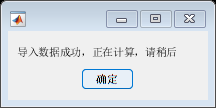

            Place = Data(:,1);
            Place =table2array(Place);
            lY = Place;
            Y = categorical(Place);
            Y = reordercats(Y,Place);
            Datasize=size(Data);
            Data =Data(:,2:Datasize(2));
            Data = table2array(Data);
            X=Data;
            msgbox("导入数据成功，正在计算，请稍后");

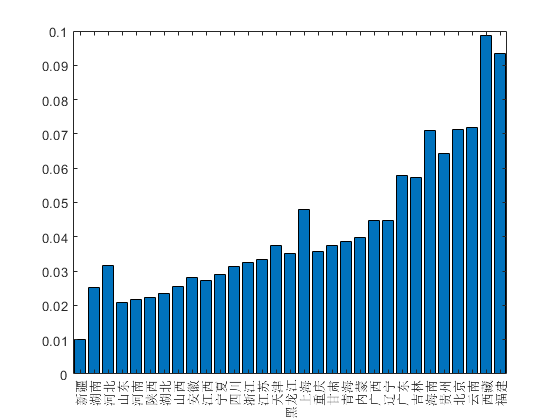

            
            %%  第二步：判断是否需要正向化
            [n,~] = size(X);
            X = Min2Max(X);
            %% 第三步：对正向化后的矩阵进行标准化
            Z = X ./ repmat(sum(X.*X) .^ 0.5, n, 1);
            %% 让用户判断是否需要增加权重
            weight = Entropy_Method(Z);
            %% 第四步：计算与最大值的距离和最小值的距离，并算出得分
            D_P = sum([(Z - repmat(max(Z),n,1)) .^ 2 ] .* repmat(weight,n,1) ,2) .^ 0.5;   % D+ 与最大值的距离向量
            D_N = sum([(Z - repmat(min(Z),n,1)) .^ 2 ] .* repmat(weight,n,1) ,2) .^ 0.5;   % D- 与最小值的距离向量
            S = D_N ./ (D_P+D_N);    % 未归一化的得分
            % disp('最后的得分为：')
            stand_S = S / sum(S)+0.01;
            
            figure;
            bar(Y,stand_S);

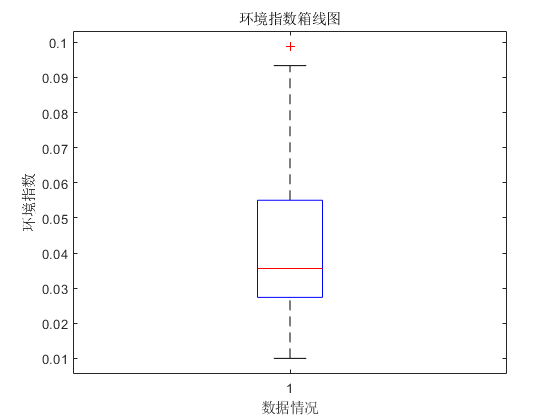

            
            boxplot(stand_S);
            title('环境指数箱线图')
            xlabel('数据情况')
            ylabel('环境指数')

            
            [~,index] = sort(stand_S);
            meanstand_s = mean(stand_S);
            mean.Value = meanstand_s;
            
            lownumber = 0;
            for i = 1:n
                if stand_S(i)<=meanstand_s
                    lownumber =lownumber + 1;
                end
            end
            
            Value = num2str(lownumber);
            
            order = 1:n;
            order = flip(order);
            order =order';
            order = num2cell(order);
            nX=stand_S(index);
            nX = num2cell(nX);
            nY=lY(index);
            nY = cell(nY);
            
            XY = [nY nX order];
%             XY = str2cell(XY);
            %
            %             [~,index] = sort(stand_S);
            
           Data=XY;
            %
            %             [~,index] = sort(stand_S);
            
